S = []


S =

     []



Yall = [];
for i = 1:10
    tempFile = strcat('Kaneshiro_etAl_objectCategoryEEG/S', num2str(i));
    tempFile = strcat(tempFile, '.mat');
    trial = load(tempFile);
    S = [S;trial]
    Yall = [Yall trial.categoryLabels];
end

S =                sub: 'S1'
                Fs: 62.5000
                 N: 32
                 T: 5188
    exemplarLabels: [1×5188 double]
    categoryLabels: [1×5188 double]
                 X: [5188×3968 double]


S =   2×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   3×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   4×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   5×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   6×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   7×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   8×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   9×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X


S =   10×1 struct array with fields:

    sub
    Fs
    N
    T
    exemplarLabels
    categoryLabels
    X



predictedLabelsAll =

     []




correctLabelsAll =

     []



accuracy =     0.8254
    0.8115
    0.8049
    0.8051
    0.8005
    0.8020
    0.8009
    0.7972
    0.7968
    0.7955


confusionMatrix =    272   164   136   114   116    64
   231   244   144   102    80    63
   257   161   187   105    88    67
   242   158   156   140    96    73
   243   138   140   135   113    95
   240   148   152   102   117   105


Output argument "confusionMatrix2" (and maybe others) not assigned during call to "createConfusionMatrixRandomForest2".

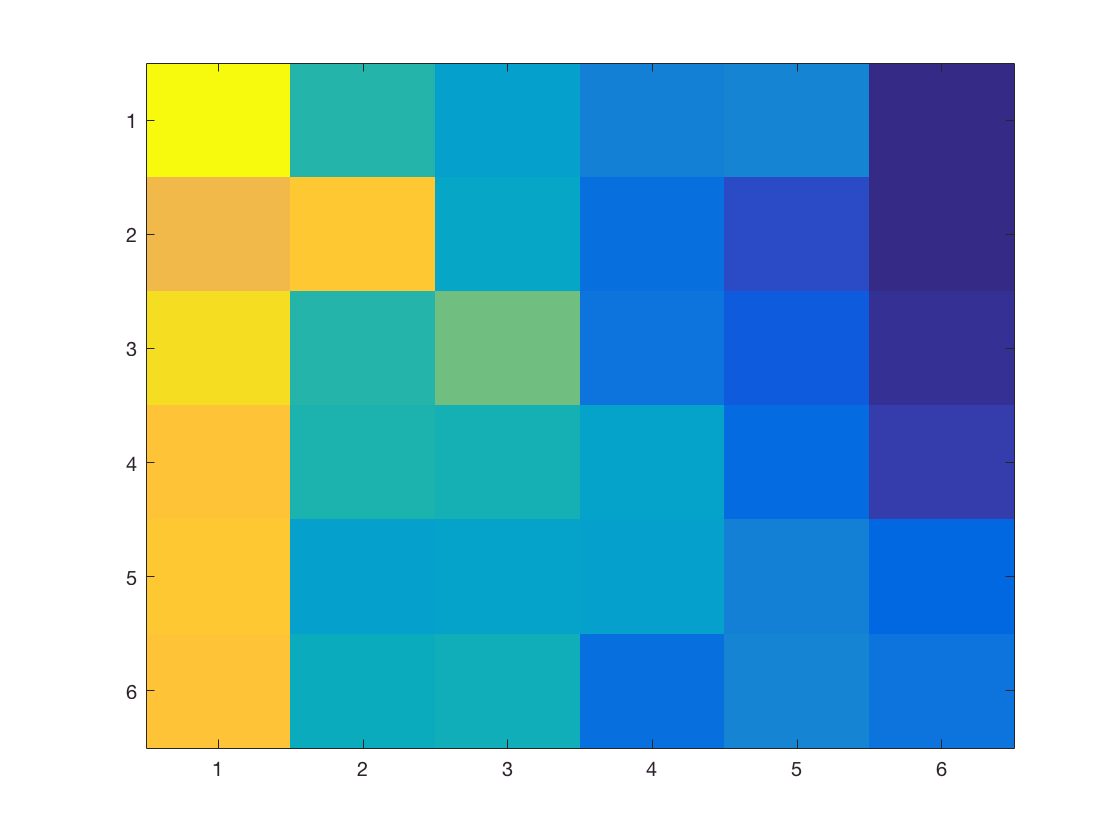

subUse = 2;
X = S(subUse).X;
Y = transpose(S(subUse).categoryLabels);

%[cm, cm2, acc, tfi] = createConfusionMatrix(X,Y);
[cm, acc, tfi] = RandomForest(X,Y, 10);

%cm2 = confusionmat(Y,lab);
title(['subject' num2str(subUse)   ])
imagesc(cm);
%imagesc(cm2);